## Deaths sequences with a defined probability

Define Probability (here normal)

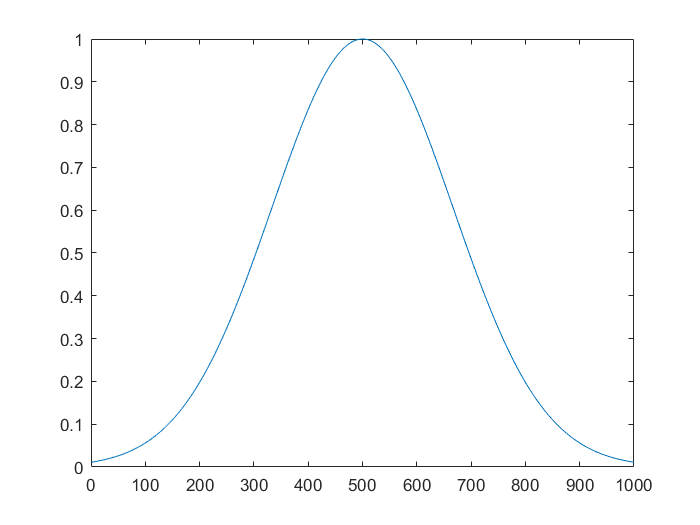



input = 500; 

pm = input/(input+1);

cov = input/3; %sqrt(input)*1.8;
x = 1:1:input*2;
y = exp(-(x-input).^2 / (2*cov^2));
figure(), plot(x,y)

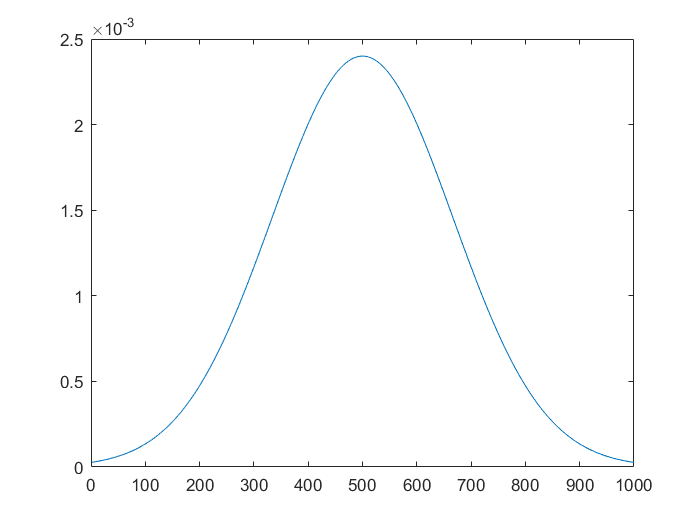


y=y' / sum(y);
figure(), plot(x,y)

## Test

% tp = 1: plot probability
% tp = 0: test length = lengthm
tp = 0;
lengthm = 5000;

res = [];
testi = [];

if tp == 1
	lengthm = 1;
end
for t=1:lengthm	
	stop = 0;
	counter = 0;
	while stop==0
		cv = rand(2,1);
		counter = counter + 1;
		%uniform
		%p = (input+(input-counter))/(input+(input-counter)+1);
		%normal
		p = 1- y(counter)/(1-sum(y(1:counter-1)));
		%exponentially decreasing
		%p=pm;
		if counter == input*2
			p = 0;
		end
		if tp == 1
			stop = counter >= input*2;
			testi = [testi p];
		else
			stop = cv(2) > p;
		end
	end
	res = [res counter]; 
end

mean(res)

ans = 502.2830

std(res)

ans = 164.2111

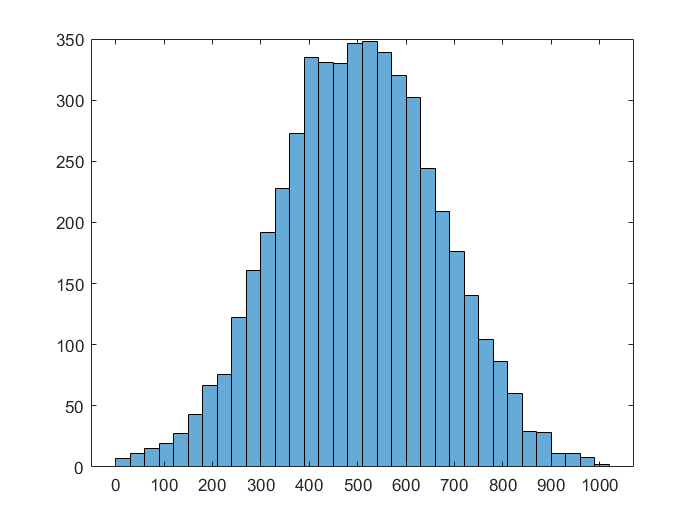


if tp == 1
	figure(),plot(testi)
else
	figure(),histogram(res)
end

## Test Probability

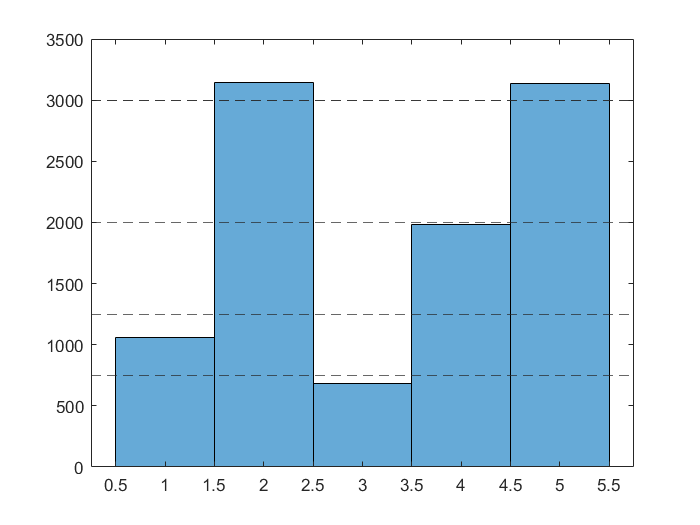


ppp = [0.25 0.60 0.15 0.4 0.6];
ppp = ppp/sum(ppp);
n = length(ppp);
N = 10000;
pop = [];
for i=1:N
	% wrong 1
	%sp = rand(1,2) - (1-ppp);
	% wrong 2
	%sp = rand(1,2) .* (ppp);
	%wrong 3 to recast
	%stop = 0;
	%while stop == 0
		sp = rand(1,n);
		ttsp = (sp>(1-ppp));
		if sum(ttsp) > 0
			sp = ttsp .* sp;
		else
			%wrong 5: to do nothing;
			%
			% wrong 6: almost but not quite
			%sp = sp - (1-ppp);
			sp = sp .* ppp;
		end		
		
		%wrong 4
		%if sum(sp)== 0
		%	sp = (ppp==max(ppp)) .* [1 2];
		%end
	%end
	
	pop = [pop sum((sp==max(sp)) .* [1:1:n])];
	if pop(i) == 3
		sp = 1;
	end
	clc;
end

figure(),histogram(pop), hold on;
for i=1:n
	yline(ppp(i)*N, '--');
end


## Test workload


primary_wl = 4;
while 1

hm_min = 0

	hmp = rand(1) + 0.4
	hmp = hmp + (hmp>1)*(1-hmp) + (hmp<hm_min)*(hm_min-hmp);
	
	sp = rand(1,5)
	new_wl = rand(1,5) > 0.5
	
	%hmp = 1;
	%sp = A;
	%new_wl = B;
	
	sp = sp.*(wl_comb_array(primary_wl,:)|(new_wl>0));
	
	sp = sp - (sp<=0).*sp + (sp<=0.001)*0.001;
	sp = sp + new_wl;
	% Remove excessive secondary wls
	while sum(sp>0) > max_num_wl-1
		spmin = min(sp(sp>0&sp<1));
		if isempty(spmin)
			break;
		end
		sp = sp - sp.*(sp==spmin);
	end
	% Compute how much? secondary wls
	sp = sp - new_wl;
	% Fix case sp=0 and new_wl != 0
	if sum(sp) == 0
		sp = wl_comb_array(primary_wl,:);
	end
	% Normalize on 1-hmp, and forzing hmp to be <1 in case new_wl != 0
	if sum(new_wl)>0
		max_hmp = max(hm_min, 1 - min_secondary_space*min(max_num_wl,sum(wl_comb_array(primary_wl,:)))); 
		hmp = hmp - (hmp>max_hmp)*(hmp-(max_hmp));
	end
	sp = sp/sum(sp)*(1-hmp);
	
	if (sum(sp<0) > 0)
		stop = 1;
	end
	
	clc;
end



hmp = 1.3246

sp =     0.2238    0.3736    0.0875    0.6401    0.1806


new_wl = 1×5 logical array
   0   1   0   1   0


Unrecognized function or variable 'wl_comb_array'.

## Interpolate GHZ_per_Watt


input = 0.5:0.1:3.45;
input = input';

vi = hpc.FV_table( sum(input.*ones(length(input),hpc.FV_levels) > hpc.FV_table(:,3)',2) + 1, 1);

di = [ [1 0 0 0 0];[0 1 0 0 0];[0 0 1 0 0];[0 0 0 1 0];[0 0 0 0 1]; 
		[0.5 0.5 0 0 0];[0.5 0 0.5 0 0];[0.5 0 0 0.5 0];[0.5 0 0 0 0.5];

Unable to resolve the name 'hpc.FV_table'.

		[0 0.5 0.5 0 0];[0 0.5 0 0.5 0];[0 0.5 0 0 0.5];
		[0 0 0.5 0.5 0];[0 0 0.5 0 0.5];
		[0.2 0.2 0.2 0.2 0.2]
];

Ti = 25:20:85;
Ti =  273.15 + Ti';

idx = 1;

for j=1:length(input)
	for i=1:length(di)	
		for k=1:length(Ti)
			res(idx,1) = hpc.power_compute(input(j), vi(j), Ti(k), di(i,:), 1);
			res(idx,2) = input(j);
			idx = idx + 1;
		end
	end	
end

figure();
scatter(res(:,2), res(:,1)), hold on;
ky = [ones(length(res),1) res(:,2)]\res(:,1)
plot(input, ky(1) + input*ky(2))



figure()
scatter(res(:,2), res(:,1)), hold;
ky = [res(:,2)]\res(:,1)
plot(input, input*ky)


%%
close all;

% Noise and Variation
hpc.model_variation = 1;
hpc = hpc.create_core_pw_noise();
hpc.measure_noise = 1;

% External Ambient Temperature
temp_amb = 25.0 + 273.15;

for i=0:2
	% Create Thermal Model:
	hpc = hpc.create_thermal_model(i);

	hpc.simulate_aut(1.5,13, 3);
end




vdd_alpha = 0.3095;
FV_table = [0.50, 0.40, 1.3500;
				 0.55, 0.40, 1.6000;
				 0.60, 1.35, 1.8000;
				 0.65, 1.35, 2.0000;
				 0.70, 1.35, 2.2000;
				 0.75, 1.60, 2.4000;
				 0.80, 1.80, 2.6000;
				 0.85, 1.80, 2.7500;
				 0.90, 2.00, 2.9000;
				 0.95, 2.00, 3.0500;
				 1.00, 2.00, 3.2000;
				 1.05, 2.60, 3.3500;
				 1.10, 2.60, 3.4500;
				 1.15, 2.60, 3.5500;
				 1.20, 2.60, 3.6600];


figure();
plot(FV_table(:,3), FV_table(:,1))
hold;
plot( [ FV_table(1,3) FV_table(end,3)], [ FV_table(1,3) FV_table(end,3)] * vdd_alpha + 0.07)



## ?????

Current plot held


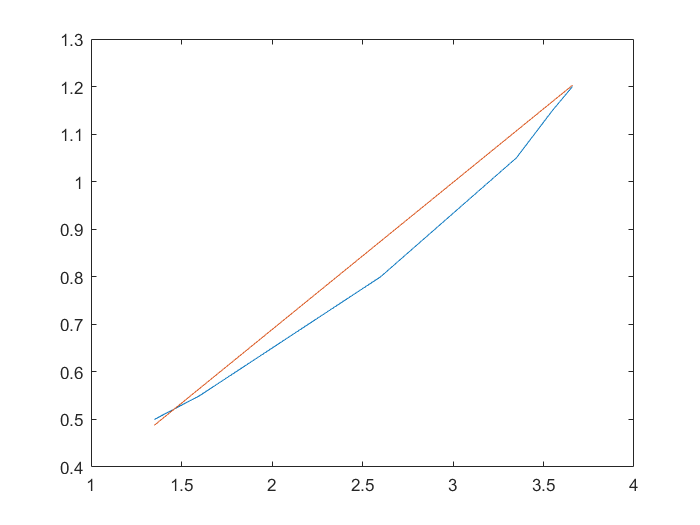


ply = 3;

figure()
plot(obj.FV_table(:,3), polyval( polyfit(obj.FV_table(:,3),obj.FV_table(:,1), ply), obj.FV_table(:,3))), hold on
plot(obj.FV_table(:,3), (obj.FV_table(:,3)\obj.FV_table(:,1))*obj.FV_table(:,3)), hold on
plot(obj.FV_table(:,3),obj.FV_table(:,1)), legend, grid on

max(diag(Fi)*obj.VDom)'



## MAX PERF MEASURE



for wli=1:3%wl_times
	
	tic
		
	bwl = 1;
	switch wli
		case 1
			%full vector	
			ll = ceil(hpc.tsim*1e6/hpc.quantum_us);
			hpc.wrplot = zeros(hpc.Nc, hpc.ipl, ll);
			hpc.wrplot(:,5,:) = 1;
			% Max Freq all time:
			hpc.frplot = 3.45 * ones(min(ceil(hpc.tsim / hpc.Ts_input)+1,(hpc.tsim/hpc.Ts_ctrl+1)), hpc.Nc);
		case 2
			%full idle but 9 cores
			ll = ceil(hpc.tsim*1e6/hpc.quantum_us);
			hpc.wrplot = zeros(hpc.Nc, hpc.ipl, ll);
			hpc.wrplot(:,bwl,:) = 1;
			
			% Med Freq all time:
			hpc.frplot = hpc.F_min * ones(min(ceil(hpc.tsim / hpc.Ts_input)+1,(hpc.tsim/hpc.Ts_ctrl+1)), hpc.Nc);
			
			coreid = [4 8 12 17 20 22 27 31 36];			
			hpc.wrplot(coreid,bwl,:) = 0;
			hpc.wrplot(coreid,5,:) = 1;
			% Max Freq all time:
			hpc.frplot(:, coreid) = 3.45;
			
			coreid = [1 10 11 14 16 24 29 32 34];			
			hpc.wrplot(coreid,bwl,:) = 0;
			hpc.wrplot(coreid,3,:) = 0.70;
			hpc.wrplot(coreid,2,:) = 0.30;
			hpc.frplot(:, coreid) = 2.7;
		case 3
			hpc.wrplot = wlwl3;
			% Max Freq all time:
			hpc.frplot = 3.45 * ones(min(ceil(hpc.tsim / hpc.Ts_input)+1,(hpc.tsim/hpc.Ts_ctrl+1)), hpc.Nc);
		case 4
			hpc.wrplot = wlwl3;
			% Max Freq all time:
			hpc.frplot = 3.45 * ones(min(ceil(hpc.tsim / hpc.Ts_input)+1,(hpc.tsim/hpc.Ts_ctrl+1)), hpc.Nc);
	end
	
	hpc.max_exec_test()
	
end

